clear;clc;

## 数据准备

仓库位置 列向量 8个

Hubs=[28 23 35 31 22 36 29 38]';
% 企业位置 3个
Enterprises=[24 41 34]';
% 储备库位置2个
Stores=[27 30]';
% w为距离矩阵
n=42;w=zeros(n);
    w(41,42)=26;w(28,42)=32;w(15,42)=28;
    w(6,41)=48;
    w(6,40)=30;w(5,40)=38;w(9,40)=28;w(27,40)=32;
    w(30,39)=15;w(32,39)=62;w(35,39)=102;w(5,39)=85;
    w(32,38)=68;w(37,38)=35;
    w(33,37)=38;
    w(33,36)=40;w(3,36)=60;
    w(32,35)=98;
    w(32,34)=25;w(1,34)=45;
    w(1,33)=60;
    w(31,32)=50;
    w(9,31)=52;
    w(29,30)=62;w(4,30)=70;
    w(28,29)=60;w(4,29)=40;
    w(8,28)=50;
    w(11,27)=48;w(40,27)=32;w(13,27)=50;w(7,27)=70;w(26,27)=70;w(9,27)=40;
    w(25,26)=18;w(19,26)=28;w(24,26)=30;
    w(11,25)=40;w(18,25)=30;w(15,25)=46;
    w(20,24)=50;
    w(14,23)=50;w(17,23)=52;w(16,23)=65;w(18,23)=45;
    w(19,22)=72;w(21,22)=45;w(20,22)=80;
    w(16,21)=58;
    w(13,20)=68;
    w(18,19)=22;
    w(16,18)=75;
    w(14,17)=56;

    w(8,15)=38;w(11,15)=56;
    w(8,14)=36;
    w(12,13)=80;
    w(10,12)=52;
    w(6,11)=32;
    w(7,10)=48;w(3,10)=42;
    w(2,9)=62;

    w(2,7)=50;
    w(4,6)=30;
    w(4,5)=10;
    w(2,3)=35;
    w(1,2)=40;
w=w+w';
w(w==0)=inf;%所有走不通的路都是无穷
w(1:n+1:n^2)=0;%对角线替换0
% a为路的等级矩阵 1表示边为高等级公路 0表示不是
a=zeros(n);
    a(5,40)=1;a(27,40)=1;
    a(35,39)=1;a(5,39)=1;
    a(4,29)=1;
    a(8,28)=1;
    a(11,27)=1;a(40,27)=1;a(13,27)=1;a(7,27)=1;
    a(11,25)=1;a(18,25)=1;
    a(16,18)=1;
    a(14,17)=1;
    a(8,15)=1;a(11,15)=1;
    a(8,14)=1;
    a(6,11)=1;
    a(7,10)=1;
    a(4,6)=1;
    a(4,5)=1;
    a=a+a';
a(1:n+1:n^2)=0;%对角线替换0

## 计算价格矩阵

%每段路的价格，普通收1.2 高级收2=1.2+0.8
wp=1.2*w+0.8*a;

## 计算3企业2仓库到各个存储地的最短费用与路线

%构造重要节点之间的最短路径矩阵minp与相应的路径元胞mpath
minp=zeros(n);
mpath=cell(n,n);
for i=1:length(Enterprises)
    for j=1:length(Hubs)
        [minp(Enterprises(i),Hubs(j)),mpath{Enterprises(i),Hubs(j)}]=mindistance(wp,Enterprises(i),Hubs(j));
        mpath{Hubs(j),Enterprises(i)}=fliplr(mpath{Enterprises(i),Hubs(j)});%这是为了添加反方向的路，方便调用.
    end
end
for i=1:length(Enterprises)
    for j=1:length(Stores)
        [minp(Enterprises(i),Stores(j)),mpath{Enterprises(i),Stores(j)}]=mindistance(wp,Enterprises(i),Stores(j));
        mpath{Stores(j),Enterprises(i)}=fliplr(mpath{Enterprises(i),Stores(j)});
    end
end
for i=1:length(Hubs)
    for j=1:length(Stores)
    [minp(Hubs(i),Stores(j)),mpath{Hubs(i),Stores(j)}]=mindistance(wp,Hubs(i),Stores(j));
    mpath{Stores(j),Hubs(i)}=fliplr(mpath{Hubs(i),Stores(j)});
    end
end
for i=1:length(Hubs)
    for j=1:length(Hubs)
[minp(Hubs(i),Hubs(j)),mpath{Hubs(i),Hubs(j)}]=mindistance(wp,Hubs(i),Hubs(j));
    end
end
minp=minp+minp';
minp(minp==0)=inf;%所有走不通的路都是无穷
minp(1:n+1:n^2)=0%对角线替换0

minp =      0   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf     0   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf     0   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf     0   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf

## 第一天，3企业2仓库全部供给国库，然后1750-1700还剩下50，这个50先不发放，作为虚拟销售地，单独运算

计划采用lingo求解，但是又不想自己输入矩阵，所有让matlab自己运算矩阵

### 运输问题模型：

构建运输问题的运价矩阵Yun0,0是因为这发生在第0天

Yun0=zeros(3,5);
Yun0(3,:)=0;
for i=1:length(Stores)
    for j=1:length(Enterprises)
        Yun0(i,j)=minp(Stores(i),Enterprises(j));
    end
end
for i=1:2
    for j=1:2
        Yun0(i,j+3)=minp(Stores(i),Hubs(2*j+1));
    end
end
Yun0

Yun0 =   120.0000  155.2000  200.4000  288.0000  204.0000
  266.4000  178.4000  122.4000  141.2000  350.4000
         0         0         0         0         0


构建产量列向量Chan0,0是因为这发生在第0天

Chan0=[500;300;400;150;400]

Chan0 =    500
   300
   400
   150
   400


构建需求列向量Xv0,0是因为这发生在第0天

Xv0=[1000;700;50]

Xv0 =         1000
         700
          50


有个睿智的消息是这个运输问题有3*5个变量，因为lingo对于大规模数据输入很不友好，我决定matlab一条路走到黑。

用来求解线性规划的函数为`x = linprog(`[`f`](https://localhost:31515/static/help/optim/ug/linprog.html?snc=MNCJYF&container=jshelpbrowser#buusznx-f)`,`[`A`](https://localhost:31515/static/help/optim/ug/linprog.html?snc=MNCJYF&container=jshelpbrowser#buusznx-A)`,`[`b`](https://localhost:31515/static/help/optim/ug/linprog.html?snc=MNCJYF&container=jshelpbrowser#buusznx_sep_shared-b)`,`[`Aeq`](https://localhost:31515/static/help/optim/ug/linprog.html?snc=MNCJYF&container=jshelpbrowser#buusznx-Aeq)`,`[`beq`](https://localhost:31515/static/help/optim/ug/linprog.html?snc=MNCJYF&container=jshelpbrowser#buusznx_sep_shared-beq)`,`[`lb`](https://localhost:31515/static/help/optim/ug/linprog.html?snc=MNCJYF&container=jshelpbrowser#buusznx-lb)`,`[`ub`](https://localhost:31515/static/help/optim/ug/linprog.html?snc=MNCJYF&container=jshelpbrowser#buusznx-ub)`)`

`其中Ax<=b Aeq*x=beq lb<=x<=ub`

f=[];
for i=1:size(Yun0,1)
    f=[f,Yun0(i,:)];
end
%matlab版arr.append
b=[Xv0;Chan0]';
A=zeros(length(b),size(Yun0,1)*size(Yun0,2));
dim1=size(A,1);%行数，而且是产地+销售地
dim2=size(A,2);%列数
dim1_Yun0=size(Yun0,1);%行数
dim2_Yun0=size(Yun0,2);%列数
for i=1:dim1
    if i<=length(Xv0)
        A(i,dim2_Yun0*i-dim2_Yun0+1:dim2_Yun0*i)=1;
    else
        for j=1:dim1_Yun0
            A(i,(i-length(Xv0))+(j-1)*dim2_Yun0)=1;
        end
    end
end
lb=zeros(1,size(Yun0,1)*size(Yun0,2));
ub=ones(1,size(Yun0,1)*size(Yun0,2))*inf;
[solve0,optim0]=linprog(f,[],[],A,b,lb,ub)


Optimal solution found.



solve0 =    500
   150
     0
     0
   350
     0
   150
   400
   150
     0


optim0 = 251580

solution0=[];
for i=1:size(Yun0,1)
    solution0=[solution0,solve0(size(Yun0,2)*i-size(Yun0,2)+1:size(Yun0,2)*i)];
end
solution0=solution0'

solution0 =    500   150     0     0   350
     0   150   400   150     0
     0     0     0     0    50


sum(solution0)%验证一下，没毛病

ans =    500   300   400   150   400


sum(solution0,2)%同上

ans =         1000
         700
          50


总算构造出来了，这个操作真叫人窒息，写一个函数[solution,optim]=YunShu2LinePro(Yun,Xv,Chan)来封装一下。

[solution0,optim0]=YunShu2LinePro(Yun0,Xv0,Chan0)


Optimal solution found.



solution0 =    500   150     0     0   350
     0   150   400   150     0
     0     0     0     0    50


optim0 = 251580

但是这还不够，我想要直接打印一个用元胞数组表示出来的表格

mini_path0=cell(2,5);
for i=1:length(Stores)
    for j=1:length(Enterprises)
        mini_path0{i,j}=mpath{Stores(i),Enterprises(j)};
    end
end
for i=1:2
    for j=1:2
        mini_path0{i,j+3}=mpath{Stores(i),Hubs(2*j+1)};
    end
end
mini_path0

mini_path0 = 2×5 cell 数组
    {1×3 double}    {1×4 double}    {1×5 double}    {1×5 double}    {1×4 double}
    {1×7 double}    {1×4 double}    {1×4 double}    {1×3 double}    {1×8 double}


## 从上面题目中可见多余的50集中在仓库5里面，现在考虑仓库5对多个其他仓库的单独分配

模型

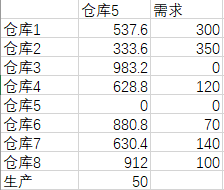

Yun1=zeros(8,1);
for i=1:length(Hubs)
    Yun1(i,1)=minp(Hubs(5),Hubs(i));
end
Yun1

Yun1 =   537.6000
  333.6000
  983.2000
  628.8000
         0
  880.8000
  630.4000
  912.0000


## 这个压根不用计算，直接看哪里价格最低然后yun过去就行了，得到规划仓库5运给仓库2 50单位，路线

mini_path1=mpath{Hubs(5),Hubs(2)}

mini_path1 =     22    19    18    23


optim1=50*minp(Hubs(5),Hubs(2))

optim1 = 16680

## 进入第二阶段，计算生产到爆的操作

需求量1030 估算产量每天90，那么需要90*12=1080天生产，才能恰好比需求多50，可以直接存在企业仓库

这里假设第二天早上才开始分配第一天的生产物资，并且当天之内可以运完

后面时间同理，所以要13天当天才能分配完，后续经过运算，可以一直存储在企业仓库内

模型

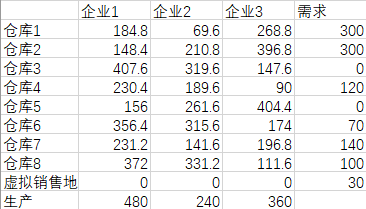

Yun2=zeros(9,3);
Yun2(9,:)=0;
for i=1:length(Hubs)
    for j=1:length(Enterprises)
        Yun2(i,j)=minp(Hubs(i),Enterprises(j));
    end
end
Yun2

Yun2 =   184.8000   69.6000  268.8000
  148.4000  210.8000  396.8000
  407.6000  319.6000  147.6000
  230.4000  189.6000   90.0000
  156.0000  261.6000  404.4000
  356.4000  315.6000  174.0000
  231.2000  141.6000  196.8000
  372.0000  331.2000  111.6000
         0         0         0


求Xv2 Chan2,然后一通操作

Xv2=[300
300
0
120
0
70
140
100
50];
Chan2=[480	240	360
]';

[solution2,optim2]=YunShu2LinePro(Yun2,Xv2,Chan2)


Optimal solution found.



solution2 =     60   240     0
   300     0     0
     0     0     0
     0     0   120
     0     0     0
     0     0    70
    70     0    70
     0     0   100
    50     0     0


optim2 = 136412

mini_path2=cell(8,3);
for i=1:length(Hubs)
    for j=1:length(Enterprises)
        mini_path2{i,j}=mpath{Hubs(i),Enterprises(j)};
    end
end

mini_path2

mini_path2 = 8×3 cell 数组
    {1×6 double}    {1×3 double}    {1×6 double}
    {1×5 double}    {1×6 double}    {1×9 double}
    {1×9 double}    {1×6 double}    {1×3 double}
    {1×5 double}    {1×5 double}    {1×3 double}
    {1×3 double}    {1×7 double}    {1×8 double}
    {1×7 double}    {1×7 double}    {1×4 double}
    {1×7 double}    {1×4 double}    {1×5 double}
    {1×7 double}    {1×7 double}    {1×3 double}


接下来计算剩余到第20天送完前19天后各个仓库储存量

其实不用计算，所有仓库都达到预期存储

仓库1 50+40×8=370 仓库2 30×8=240 仓库3 20×8=160

最小费用为

optim=optim0+optim1+optim2

optim = 404672

## 到第十天如果发生洪灾的操作，假设第十天一早就发洪水

首先安排好前9天，注意根据假设第9天生产的物资要在第十天运送，所以会生产8天的量

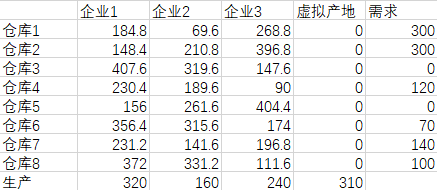

Yun2_1=zeros(8,4);
Yun2_1(:,4)=0;
for i=1:length(Hubs)
    for j=1:length(Enterprises)
        Yun2_1(i,j)=minp(Hubs(i),Enterprises(j));
    end
end
Yun2_1

Yun2_1 =   184.8000   69.6000  268.8000         0
  148.4000  210.8000  396.8000         0
  407.6000  319.6000  147.6000         0
  230.4000  189.6000   90.0000         0
  156.0000  261.6000  404.4000         0
  356.4000  315.6000  174.0000         0
  231.2000  141.6000  196.8000         0
  372.0000  331.2000  111.6000         0


Xv2_1=[300
300
0
120
0
70
140
100
];
Chan2_1=[320	160	240	310
]';

[solution2_1,optim2_1]=YunShu2LinePro(Yun2_1,Xv2_1,Chan2_1)


Optimal solution found.



solution2_1 =     20   160     0   120
   300     0     0     0
     0     0     0     0
     0     0   120     0
     0     0     0     0
     0     0    20    50
     0     0     0   140
     0     0   100     0


optim2_1 = 84792

mini_path2

mini_path2 = 8×3 cell 数组
    {1×6 double}    {1×3 double}    {1×6 double}
    {1×5 double}    {1×6 double}    {1×9 double}
    {1×9 double}    {1×6 double}    {1×3 double}
    {1×5 double}    {1×5 double}    {1×3 double}
    {1×3 double}    {1×7 double}    {1×8 double}
    {1×7 double}    {1×7 double}    {1×4 double}
    {1×7 double}    {1×4 double}    {1×5 double}
    {1×7 double}    {1×7 double}    {1×3 double}


## 第十天发洪水，现在生成第十天开始的minpH与mpathH

### 创建新的wpH

% w为距离矩阵
n=42;wH=zeros(n);
    wH(14,23)=inf;
    wH(11,25)=inf;
    wH(26,27)=inf;
    wH(9,31)=inf;
wH=wH+wH'+w;
wpH=1.2*wH+0.8*a

wpH =          0   48.0000       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf   72.0000   54.0000       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf
   48.0000         0   42.0000       Inf       Inf       Inf   60.0000       Inf   74.4000       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf
       Inf   42.0000         0       Inf       Inf       Inf       Inf       Inf       Inf   50.4000       Inf       Inf       Inf       Inf       Inf  

### 计算3企业2仓库到各个存储地的最短费用与路线

%构造重要节点之间的最短路径矩阵minipH与相应的路径元胞mpathH
minipH=zeros(n);
mpathH=cell(n,n);
for i=1:length(Enterprises)
    for j=1:length(Hubs)
        [minipH(Enterprises(i),Hubs(j)),mpathH{Enterprises(i),Hubs(j)}]=mindistance(wpH,Enterprises(i),Hubs(j));
        mpathH{Hubs(j),Enterprises(i)}=fliplr(mpathH{Enterprises(i),Hubs(j)});%这是为了添加反方向的路，方便调用.
    end
end
for i=1:length(Enterprises)
    for j=1:length(Stores)
        [minipH(Enterprises(i),Stores(j)),mpathH{Enterprises(i),Stores(j)}]=mindistance(wpH,Enterprises(i),Stores(j));
        mpathH{Stores(j),Enterprises(i)}=fliplr(mpathH{Enterprises(i),Stores(j)});
    end
end
for i=1:length(Hubs)
    for j=1:length(Stores)
    [minipH(Hubs(i),Stores(j)),mpathH{Hubs(i),Stores(j)}]=mindistance(wpH,Hubs(i),Stores(j));
    mpathH{Stores(j),Hubs(i)}=fliplr(mpathH{Hubs(i),Stores(j)});
    end
end
for i=1:length(Hubs)
    for j=1:length(Hubs)
[minipH(Hubs(i),Hubs(j)),mpathH{Hubs(i),Hubs(j)}]=mindistance(wpH,Hubs(i),Hubs(j));
    end
end
minipH=minipH+minipH';
minipH(minipH==0)=inf;%所有走不通的路都是无穷
minipH(1:n+1:n^2)=0%对角线替换0

minipH = 	1.0e+03 *

         0       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf
       Inf         0       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf
       Inf       Inf         0       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       

### 进入第二阶段，计算生产到爆的操作

需求量310估算产量每天90，那么需要90*4天=360生产，才能恰好比需求多50，可以直接存在企业仓库

后面时间同理，所以要13天当天才能分配完，后续经过运算，可以一直存储在企业仓库内

模型

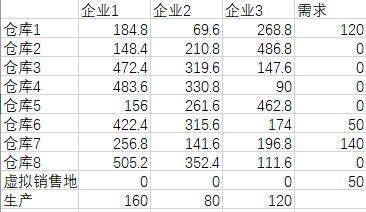

Yun3=zeros(9,3);
Yun3(9,:)=0;
for i=1:length(Hubs)
    for j=1:length(Enterprises)
        Yun3(i,j)=minipH(Hubs(i),Enterprises(j));
    end
end
Yun3

Yun3 =   184.8000   69.6000  268.8000
  148.4000  210.8000  486.8000
  472.4000  319.6000  147.6000
  483.6000  330.8000   90.0000
  156.0000  261.6000  462.8000
  422.4000  315.6000  174.0000
  256.8000  141.6000  196.8000
  505.2000  352.4000  111.6000
         0         0         0


求Xv3 Chan3,然后一通操作

Xv3=[120
0
0
0
0
50
140
0
50
];
Chan3=[160	80	120

]';

[solution3,optim3]=YunShu2LinePro(Yun3,Xv3,Chan3)


Optimal solution found.



solution3 =     40    80     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0    50
    70     0    70
     0     0     0
    50     0     0


optim3 = 5.3412e+04

mini_path3=cell(8,3);
for i=1:length(Hubs)
    for j=1:length(Enterprises)
        mini_path3{i,j}=mpath{Hubs(i),Enterprises(j)};
    end
end

mini_path3

mini_path3 = 8×3 cell 数组
    {1×6 double}    {1×3 double}    {1×6 double}
    {1×5 double}    {1×6 double}    {1×9 double}
    {1×9 double}    {1×6 double}    {1×3 double}
    {1×5 double}    {1×5 double}    {1×3 double}
    {1×3 double}    {1×7 double}    {1×8 double}
    {1×7 double}    {1×7 double}    {1×4 double}
    {1×7 double}    {1×4 double}    {1×5 double}
    {1×7 double}    {1×7 double}    {1×3 double}


接下来计算剩余到第20天送完前19天后各个仓库储存量

其实不用计算，所有仓库都达到预期存储

仓库1 50+40×8=370 仓库2 30×8=240 仓库3 20×8=160

最小费用为

optim=optim0+optim2_1+optim3

optim = 389784